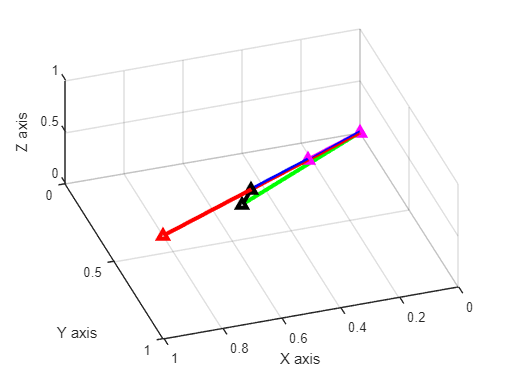

xk = [1;1;1];
xk_1 = [0;0;0];
xt = [0.5;0.3;0];

p = xk - xk_1;
pt = xt - xk_1;
d = (dot(pt,p)/dot(p,p)) * p;
delta = 0.5;
p_los = p/norm(p) * (norm(d)+delta);
los = p_los - pt;

point1 = [4,5,6];
point2 = [-3,6,-3];
origin = [0,0,0];
figure;hold on;
plot3([xk_1(1) xk(1)],[xk_1(2) xk(2)],[xk_1(3) xk(3)],'r-^', 'LineWidth',3);
plot3([xk_1(1) xt(1)],[xk_1(2) xt(2)],[xk_1(3) xt(3)],'g-^', 'LineWidth',3);
plot3([xk_1(1) p_los(1)],[xk_1(2) p_los(2)],[xk_1(3) p_los(3)],'b-^', 'LineWidth',3);
plot3([xk_1(1) d(1)],[xk_1(2) d(2)],[xk_1(3) d(3)],'m-^', 'LineWidth',3);
plot3([pt(1) p_los(1)],[pt(2) p_los(2)],[pt(3) p_los(3)],'k-^', 'LineWidth',3);
grid on;
xlabel('X axis'), ylabel('Y axis'), zlabel('Z axis')
set(gca,'CameraPosition',[1 2 3]);


wpts = [[0;0;0] [1;1;1] [3;2;2] [7;3;2]] * 10;
n_wpts = size(wpts);
n_wpts = n_wpts(2);

wn = 8;
damp = 1;

clear
R = eul2rotm([1 2 3], "XYZ");
omega = [3;2;4];
q_omega = quaternion([0;omega]');
q = quaternion(rotm2quat(R));

q_dot = 0.5*q*q_omega;

[q0 q1 q2 q3] = parts(q);

E = [-q1 q0 -q3 q2;
      -q2 q3 q0 -q1;
      -q3 -q2 q1 q0];

G = [-q1 q0 q3 -q2;
      -q2 -q3 q0 q1;
      -q3 q2 -q1 q0];

[q0d q1d q2d qd3] = parts(q_dot);
2*G*[q0d; q1d; q2d; qd3]

ans =     3.0000
    2.0000
    4.0000


R'*2*E*[q0d; q1d; q2d; qd3]

ans =     3.0000
    2.0000
    4.0000
